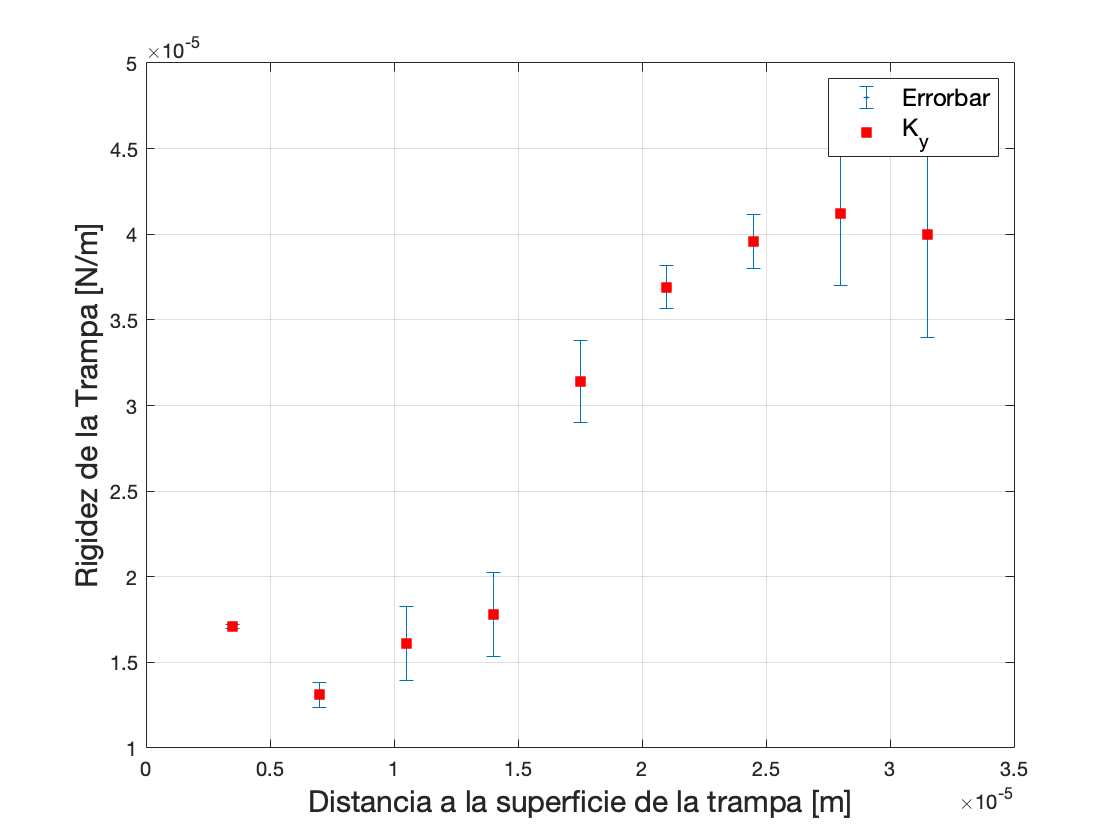

DatosK = readmatrix("k_y.txt");
d = DatosK(:,1);
k = DatosK(:,2);

c1 = -2.146e24;
c2 = 2.548e20;
c3 = -1.161e16;
c4 = 2.476e11;
c5 = -2.4e6;
c6 = 9.429;
c7 = 4.367e-6;
fk = c1*d.^6 + c2*d.^5 + c3*d.^4 +c4*d.^3 + c5*d.^2 + c6*d +c7;
er = abs(fk - k);

%%errorbar(d,fk,er,"o");
%%hold on
%%plot(d,k,"r.");
%%legend('Errorbar','K');

%%errorbar(d,fk,er,'-s','MarkerSize',1,...
    %%'MarkerEdgeColor','red','MarkerFaceColor','red')
    
errorbar(d,k,er,"*",'MarkerSize',1);
hold on 
plot(d,k,"s",'MarkerSize',6,'MarkerEdgeColor' ...
    ,'red','MarkerFaceColor','red');
legend('Errorbar','K_y','FontSize',12);
xlabel('Distancia a la superficie de la trampa [m]','FontSize',15);
ylabel('Rigidez de la Trampa [N/m]','FontSize',15);
grid on 